# Appello del 15/06/2021

## 1 Esercizio 2.

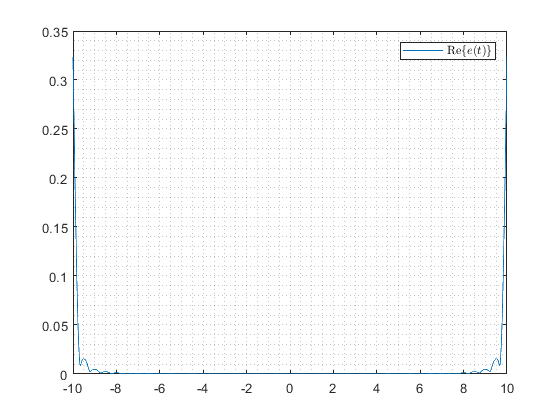

clear;
close all;
t = -10:0.01:10;
f = -15:0.01:15;
h1 = 4 * sinc(2*t).^2 .* exp(-1i * 8 * pi * t);
x = cos(10 * pi * t);
H1 = trasformataDiFourier(t, h1, f);
X = trasformataDiFourier(t, x, f);
Y1 = X .* H1;
y1 = antitrasformataDiFourier(f, Y1, t);
y2 = -cos(20 * pi * (t - 2));
y = y1 + y2;
Py = potenza(t, y);

y_analitico = y2 + 1/2 * exp(-1i * 10 * pi * t);
Py_analitico = 3/4;

err_y_y_analitico = abs(y - y_analitico);
figure;
real = plot(t, err_y_y_analitico);
grid minor;
legend(real, 'Re\{$e(t)$\}', "Interpreter", "Latex");

err_py_py_analitico = abs(Py - Py_analitico);

## 2 Esercizio 1.

clear;
close all;
t = -10:0.01:10;
u1 = exp(-t) .* rect(t / 2);
u2 = exp(t) .* rect(t / 2);

norma_u1 = norma2(t, u1);
norma_u1_analitica = sqrt(2) / (2 * exp(1)) * sqrt((exp(2) + 1) * (exp(1) + 1) * (exp(1) - 1));
err_norma_u1_norma_u1_analitica = abs(norma_u1 - norma_u1_analitica);

norma_u2 = norma2(t, u2);
norma_u2_analitica = sqrt(2) / (2 * exp(1)) * sqrt((exp(2) + 1) * (exp(1) + 1) * (exp(1) - 1));
err_norma_u2_norma_u2_analitica = abs(norma_u2 - norma_u2_analitica);

forma_bilineare_u1_u2 = formaBilineare(t, u1, u2);
forma_bilineare_u1_u2_analitica = 2;
err_forma_bilineare_u1_u2_forma_bilineare_u1_u2_analitica = abs(forma_bilineare_u1_u2 - forma_bilineare_u1_u2_analitica);

cos_between_u1_u2 = forma_bilineare_u1_u2 / (norma_u1 * norma_u2);
cos_between_u1_u2_analitica = 4 * exp(2) / (exp(4) - 1);
err_cos_between_u1_u2_cos_between_u1_u2_analitica = abs(cos_between_u1_u2 - cos_between_u1_u2_analitica);

## 2 Esercizio 2.

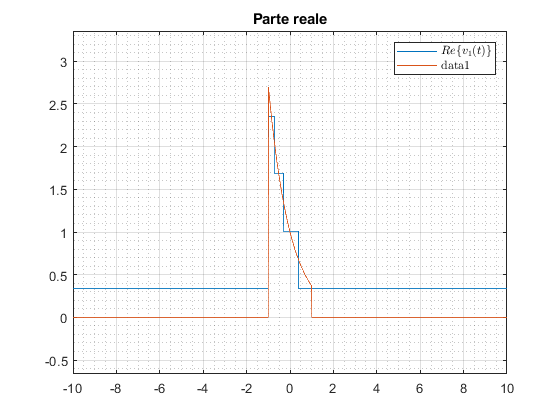

clear;
close all;
t = -10:0.01:10;
u1 = exp(-t) .* rect(t / 2);
u2 = exp(t) .* rect(t / 2);

v1 = quantizzatoreUniforme(u1, 2);
rappresentaUnSegnale(t, v1, 'v_{1}(t)');
hold on, plot(t, u1), hold off;

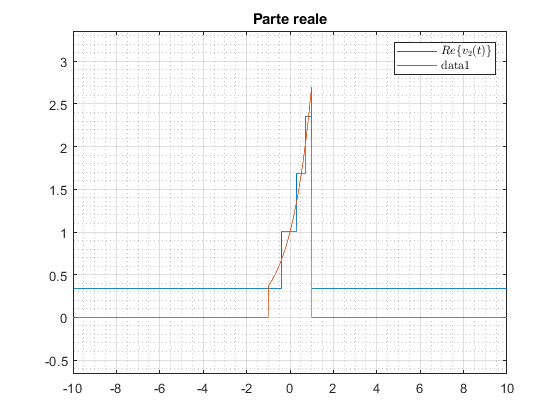

v2 = quantizzatoreUniforme(u2, 2);
rappresentaUnSegnale(t, v2, 'v_{2}(t)');
hold on, plot(t, u2), hold off;

## 2 Esercizio 3.

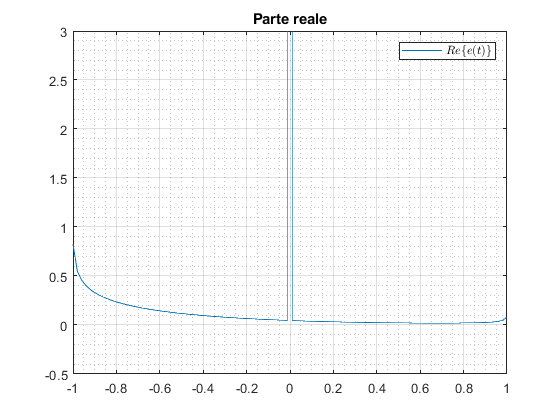

clear;
close all;
t = -100:0.01:100;
f = -150:0.01:150;
u1 = exp(-t) .* rect(t / 2);
u2 = exp(t) .* rect(t / 2);

U1 = trasformataDiFourier(t, u1, f);
Delta = 1 + zeros(size(U1));
Z1 = convoluzione(f, U1, Delta);
z1 = antitrasformataDiFourier(Z1(1, :), Z1(2, :), t);
z = z1 + u2;
z_analitica = u2 + antitrasformataDiFourier(f, Delta, t);
err_z_z_analitica = abs(z - z_analitica);
rappresentaUnSegnale(t, err_z_z_analitica, 'e(t)');
axis([-1 1 -0.5 3]);